clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[8.250;13.526;18.525];
u31=[0.340;0.563;0.753];
r2=[19.804;13.526;18.525];
u32=[0.340;0.563;0.753];
r3=[2.473;18.406;28.643];
u33=[0.340;-0.563;-0.753];
r4=[3.305;7.762;28.643];
u34=[-0.340;-0.563;-0.753];
r5=[14.859;7.762;28.643];
u35=[-0.340;-0.563;-0.753];
r6=[-2.473;2.882;18.525];
u36=[-0.340;0.563;0.753];
r7=[9.082;2.882;18.525];
u37=[-0.340;0.563;0.753];
r8=[2.473;13.526;5.059];
u38=[0.340;0.563;-0.753];



x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];
x8=[];
y8=[];
x9=[];
y9=[];

hold on 
axis([0 20 0 15]);

for R3=2.4:0.3:13 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     9.4200    2.4000    1.0005


ans =     7.9100    2.7000    1.0002


ans =     7.1800    3.0000    1.0009


ans =     6.7500    3.3000    1.0019


ans =     6.4800    3.6000    1.0005


ans =     6.2800    3.9000    1.0020


ans =     6.1400    4.2000    1.0016


ans =     6.0300    4.5000    1.0022


ans =     5.9500    4.8000    1.0012


ans =     5.8800    5.1000    1.0020


ans =     5.8300    5.4000    1.0007


ans =     5.7800    5.7000    1.0022


ans =     5.7400    6.0000    1.0030


ans =     5.7100    6.3000    1.0025


ans =     5.6900    6.6000    1.0002


ans =     5.6600    6.9000    1.0024


ans =     5.6400    7.2000    1.0023


ans =     5.6200    7.5000    1.0031


ans =     5.6100    7.8000    1.0012


ans =     5.5900    8.1000    1.0034


ans =     5.5800    8.4000    1.0026


ans =     5.5700    8.7000    1.0023


ans =     5.5600    9.0000    1.0024


ans =     5.5500    9.3000    1.0028


ans =     5.5500    9.6000    1.0001


ans =     5.5400    9.9000    1.0010


ans =     5.5300   10.2000    1.0022


ans =     5.5300   10.5000    1.0001


ans =     5.5200   10.8000    1.0017


ans =     5.5100   11.1000    1.0035


ans =     5.5100   11.4000    1.0019


ans =     5.5100   11.7000    1.0004


ans =     5.5000   12.0000    1.0025


ans =     5.5000   12.3000    1.0012


ans =     5.5000   12.6000    1.0000


ans =     5.4900   12.9000    1.0024


plot(x1,y1,'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'DisplayName','1-2')


for R3=4:0.3:13 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =    13.0400    4.0000    1.0002


ans =    12.2900    4.3000    1.0006


ans =    11.4800    4.6000    1.0003


ans =    10.6000    4.9000    1.0002


ans =     9.6500    5.2000    1.0007


ans =     8.6800    5.5000    1.0002


ans =     7.7200    5.8000    1.0002


ans =     6.8500    6.1000    1.0004


ans =     6.1200    6.4000    1.0008


ans =     5.5500    6.7000    1.0001


ans =     5.0900    7.0000    1.0009


ans =     4.7300    7.3000    1.0006


ans =     4.4300    7.6000    1.0011


ans =     4.1800    7.9000    1.0010


ans = 1×3
    3.9600    8.2000    1.0015


ans = 1×3
    3.7700    8.5000    1.0009


ans = 1×3
    3.5900    8.8000    1.0020


ans = 1×3
    3.4300    9.1000    1.0018


ans = 1×3
    3.2800    9.4000    1.0017


ans = 1×3
    3.1400    9.7000    1.0012


ans = 1×3
    3.0000   10.0000    1.0025


ans = 1×3
    2.8800   10.3000    1.0000


ans = 1×3
    2.7500   10.6000    1.0017


ans = 1×3
    2.6300   10.9000    1.0019


ans = 1×3
    2.5200   11.2000    1.0006


ans = 1×3
    2.4100   11.5000    1.0006


ans = 1×3
    2.3000   11.8000    1.0022


ans = 1×3
    2.2000   12.1000    1.0023


ans = 1×3
    2.1100   12.4000    1.0010


ans = 1×3
    2.0200   12.7000    1.0018


ans = 1×3
    1.9400   13.0000    1.0014


plot(x2,y2,'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'DisplayName','1-3')


for R3=3:0.3:13 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    6.9100    3.0000    1.0013


ans = 1×3
    6.7600    3.3000    1.0023


ans = 1×3
    6.6600    3.6000    1.0010


ans = 1×3
    6.5800    3.9000    1.0014


ans = 1×3
    6.5200    4.2000    1.0013


ans = 1×3
    6.4700    4.5000    1.0020


ans = 1×3
    6.4300    4.8000    1.0026


ans = 1×3
    6.4000    5.1000    1.0023


ans = 1×3
    6.3800    5.4000    1.0006


ans = 1×3
    6.3600    5.7000    1.0002


ans = 1×3
    6.3400    6.0000    1.0007


ans = 1×3
    6.3200    6.3000    1.0020


ans = 1×3
    6.3100    6.6000    1.0010


ans = 1×3
    6.3000    6.9000    1.0005


ans = 1×3
    6.2900    7.2000    1.0005


ans = 1×3
    6.2800    7.5000    1.0008


ans = 1×3
    6.2700    7.8000    1.0015


ans = 1×3
    6.2600    8.1000    1.0024


ans = 1×3
    6.2600    8.4000    1.0005


ans = 1×3
    6.2500    8.7000    1.0019


ans = 1×3
    6.2500    9.0000    1.0003


ans = 1×3
    6.2400    9.3000    1.0020


ans = 1×3
    6.2400    9.6000    1.0007


ans = 1×3
    6.2300    9.9000    1.0027


ans = 1×3
    6.2300   10.2000    1.0016


ans = 1×3
    6.2300   10.5000    1.0007


ans = 1×3
    6.2200   10.8000    1.0029


ans = 1×3
    6.2200   11.1000    1.0021


ans = 1×3
    6.2200   11.4000    1.0013


ans = 1×3
    6.2200   11.7000    1.0006


ans = 1×3
    6.2100   12.0000    1.0031


ans = 1×3
    6.2100   12.3000    1.0025


ans = 1×3
    6.2100   12.6000    1.0020


ans = 1×3
    6.2100   12.9000    1.0015


plot(x3,y3,'color',[63, 125, 162]/256, ...
    'LineWidth',1.5,'DisplayName','1-4')


for R3=4:0.3:13 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];   
end

ans = 1×3
   10.3500    4.0000    1.0003


ans = 1×3
    9.1100    4.3000    1.0003


ans = 1×3
    8.3700    4.6000    1.0010


ans = 1×3
    7.8900    4.9000    1.0003


ans = 1×3
    7.5400    5.2000    1.0008


ans = 1×3
    7.2800    5.5000    1.0011


ans = 1×3
    7.0800    5.8000    1.0013


ans = 1×3
    6.9200    6.1000    1.0016


ans = 1×3
    6.7900    6.4000    1.0020


ans = 1×3
    6.6900    6.7000    1.0007


ans = 1×3
    6.6000    7.0000    1.0010


ans = 1×3
    6.5200    7.3000    1.0022


ans = 1×3
    6.4600    7.6000    1.0011


ans = 1×3
    6.4000    7.9000    1.0023


ans = 1×3
    6.3600    8.2000    1.0001


ans = 1×3
    6.3100    8.5000    1.0021


ans = 1×3
    6.2800    8.8000    1.0001


ans = 1×3
    6.2400    9.1000    1.0019


ans = 1×3
    6.2100    9.4000    1.0020


ans = 1×3
    6.1900    9.7000    1.0002


ans = 1×3
    6.1600   10.0000    1.0019


ans = 1×3
    6.1400   10.3000    1.0014


ans = 1×3
    6.1200   10.6000    1.0015


ans = 1×3
    6.1000   10.9000    1.0022


ans = 1×3
    6.0900   11.2000    1.0003


ans = 1×3
    6.0700   11.5000    1.0018


ans = 1×3
    6.0600   11.8000    1.0007


ans = 1×3
    6.0400   12.1000    1.0030


ans = 1×3
    6.0300   12.4000    1.0025


ans = 1×3
    6.0200   12.7000    1.0022


ans = 1×3
    6.0100   13.0000    1.0022


plot(x4,y4,'color',[237, 125, 49]/256, ...
    'LineWidth',1.5,'DisplayName','1-5')


for R3=4:0.3:13 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];   
end

ans = 1×3
    9.6000    4.0000    1.0008


ans = 1×3
    9.2800    4.3000    1.0014


ans = 1×3
    9.0000    4.6000    1.0015


ans = 1×3
    8.7600    4.9000    1.0008


ans = 1×3
    8.5500    5.2000    1.0003


ans = 1×3
    8.3600    5.5000    1.0010


ans = 1×3
    8.2000    5.8000    1.0006


ans = 1×3
    8.0600    6.1000    1.0001


ans = 1×3
    7.9300    6.4000    1.0008


ans = 1×3
    7.8200    6.7000    1.0002


ans = 1×3
    7.7100    7.0000    1.0019


ans = 1×3
    7.6200    7.3000    1.0014


ans = 1×3
    7.5400    7.6000    1.0004


ans = 1×3
    7.4600    7.9000    1.0007


ans = 1×3
    7.3900    8.2000    1.0001


ans = 1×3
    7.3200    8.5000    1.0004


ans = 1×3
    7.2500    8.8000    1.0015


ans = 1×3
    7.1900    9.1000    1.0011


ans = 1×3
    7.1300    9.4000    1.0013


ans = 1×3
    7.0700    9.7000    1.0020


ans = 1×3
    7.0200   10.0000    1.0008


ans = 1×3
    6.9700   10.3000    1.0000


ans = 1×3
    6.9100   10.6000    1.0018


ans = 1×3
    6.8600   10.9000    1.0016


ans = 1×3
    6.8100   11.2000    1.0017


ans = 1×3
    6.7600   11.5000    1.0019


ans = 1×3
    6.7200   11.8000    1.0000


ans = 1×3
    6.6700   12.1000    1.0006


ans = 1×3
    6.6200   12.4000    1.0013


ans = 1×3
    6.5700   12.7000    1.0022


ans = 1×3
    6.5300   13.0000    1.0009


plot(x5,y5,'color',[47, 85, 151]/256, ...
    'LineWidth',1.5,'DisplayName','1-6')


for R3=3:0.3:13 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r7,R1,R3,u31,u37);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    [R1,R3,miu2]
    x6=[x6,R1];
    y6=[y6,R3];   
end

ans = 1×3
    7.6700    3.0000    1.0005


ans = 1×3
    7.2200    3.3000    1.0010


ans = 1×3
    6.8000    3.6000    1.0013


ans = 1×3
    6.4300    3.9000    1.0010


ans = 1×3
    6.1100    4.2000    1.0015


ans = 1×3
    5.8500    4.5000    1.0006


ans = 1×3
    5.6300    4.8000    1.0012


ans = 1×3
    5.4500    5.1000    1.0017


ans = 1×3
    5.3100    5.4000    1.0001


ans = 1×3
    5.1800    5.7000    1.0024


ans = 1×3
    5.0800    6.0000    1.0021


ans = 1×3
    5.0000    6.3000    1.0006


ans = 1×3
    4.9200    6.6000    1.0030


ans = 1×3
    4.8600    6.9000    1.0024


ans = 1×3
    4.8100    7.2000    1.0013


ans = 1×3
    4.7600    7.5000    1.0025


ans = 1×3
    4.7200    7.8000    1.0023


ans = 1×3
    4.6900    8.1000    1.0003


ans = 1×3
    4.6500    8.4000    1.0033


ans = 1×3
    4.6300    8.7000    1.0003


ans = 1×3
    4.6000    9.0000    1.0021


ans = 1×3
    4.5800    9.3000    1.0011


ans = 1×3
    4.5600    9.6000    1.0010


ans = 1×3
    4.5400    9.9000    1.0016


ans = 1×3
    4.5200   10.2000    1.0029


ans = 1×3
    4.5100   10.5000    1.0008


ans = 1×3
    4.4900   10.8000    1.0032


ans = 1×3
    4.4800   11.1000    1.0021


ans = 1×3
    4.4700   11.4000    1.0014


ans = 1×3
    4.4600   11.7000    1.0011


ans = 1×3
    4.4500   12.0000    1.0011


ans = 1×3
    4.4400   12.3000    1.0014


ans = 1×3
    4.4300   12.6000    1.0020


ans = 1×3
    4.4200   12.9000    1.0029


plot(x6,y6,'color',[84, 130, 53]/256, ...
    'LineWidth',1.5,'DisplayName','1-7')


for R3=3:0.3:13 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r8,R1,R3,u31,u38);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    [R1,R3,miu2]
    x7=[x7,R1];
    y7=[y7,R3];   
end

ans = 1×3
   10.5100    3.0000    1.0016


ans = 1×3
   10.3500    3.3000    1.0005


ans = 1×3
   10.1800    3.6000    1.0004


ans = 1×3
   10.0000    3.9000    1.0011


ans = 1×3
    9.8200    4.2000    1.0007


ans = 1×3
    9.6300    4.5000    1.0006


ans = 1×3
    9.4300    4.8000    1.0008


ans = 1×3
    9.2200    5.1000    1.0010


ans = 1×3
    9.0000    5.4000    1.0011


ans = 1×3
    8.7700    5.7000    1.0010


ans = 1×3
    8.5300    6.0000    1.0007


ans = 1×3
    8.2800    6.3000    1.0002


ans = 1×3
    8.0100    6.6000    1.0008


ans = 1×3
    7.7300    6.9000    1.0012


ans = 1×3
    7.4500    7.2000    1.0001


ans = 1×3
    7.1500    7.5000    1.0005


ans = 1×3
    6.8500    7.8000    1.0000


ans = 1×3
    6.5400    8.1000    1.0004


ans = 1×3
    6.2300    8.4000    1.0009


ans = 1×3
    5.9300    8.7000    1.0008


ans = 1×3
    5.6400    9.0000    1.0006


ans = 1×3
    5.3600    9.3000    1.0012


ans = 1×3
    5.1000    9.6000    1.0014


ans = 1×3
    4.8700    9.9000    1.0002


ans = 1×3
    4.6500   10.2000    1.0008


ans = 1×3
    4.4500   10.5000    1.0017


ans = 1×3
    4.2800   10.8000    1.0008


ans = 1×3
    4.1200   11.1000    1.0016


ans = 1×3
    3.9800   11.4000    1.0020


ans = 1×3
    3.8600   11.7000    1.0013


ans = 1×3
    3.7500   12.0000    1.0015


ans = 1×3
    3.6500   12.3000    1.0023


ans = 1×3
    3.5700   12.6000    1.0005


ans = 1×3
    3.4900   12.9000    1.0013


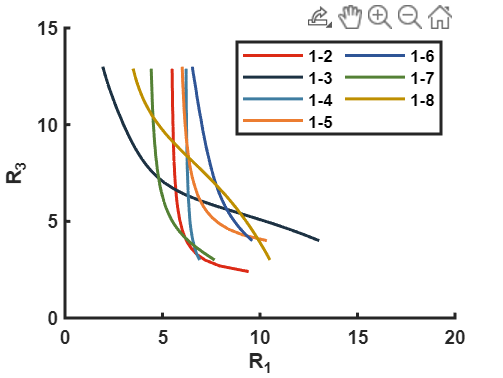

plot(x7,y7,'color',[191, 144, 0]/256, ...
    'LineWidth',1.5,'DisplayName','1-8')




set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);

hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end




